# 6. Heat Transfer -solve

Solve heat transfer or structural analysis problem

[](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.solve.html#d120e77250)

[`thermalSteadyStateResults = solve(thermalSteadyState)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.solve.html#d120e77370)`:`returns the solution to the steady-state thermal model represented in .

[`thermalTransientResults = solve(thermalTransient,tlist)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.solve.html#d120e77388)`:`returns the solution to the transient thermal model represented in at the times .

6.1**稳态热模型的解决方案**

Create a thermal model for this problem.

% thermalmodel = createpde('thermal');

Create a thermal model for this problem.

% importGeometry(thermalmodel,'C:\Users\ZGY\Desktop\structure_heat_matlab\11.stl'); 
% pdegplot(thermalmodel,'FaceLabel','on','FaceAlpha',0.5)
% axis equal

Assign material properties.

% thermalProperties(thermalmodel,'ThermalConductivity',80);

Apply a constant temperature of 100 **°**C to the left side of the block (face 4) and a constant temperature of 300 **°**C to the right side of the block (face 5). All other faces are insulated by default.

% thermalBC(thermalmodel,'Face',4,'Temperature',100);
% thermalBC(thermalmodel,'Face',5,'Temperature',300);

Mesh the geometry and solve the problem.

% generateMesh(thermalmodel);
% thermalresults = solve(thermalmodel)
% pdeplot3D(thermalmodel,'ColorMapData',thermalresults.Temperature)

6.2 瞬态热模拟：

Solve a 2-D transient thermal problem.

Create a transient thermal model for this problem.

thermalmodel = createpde('thermal','transient');

Create the geometry and include it in the model.

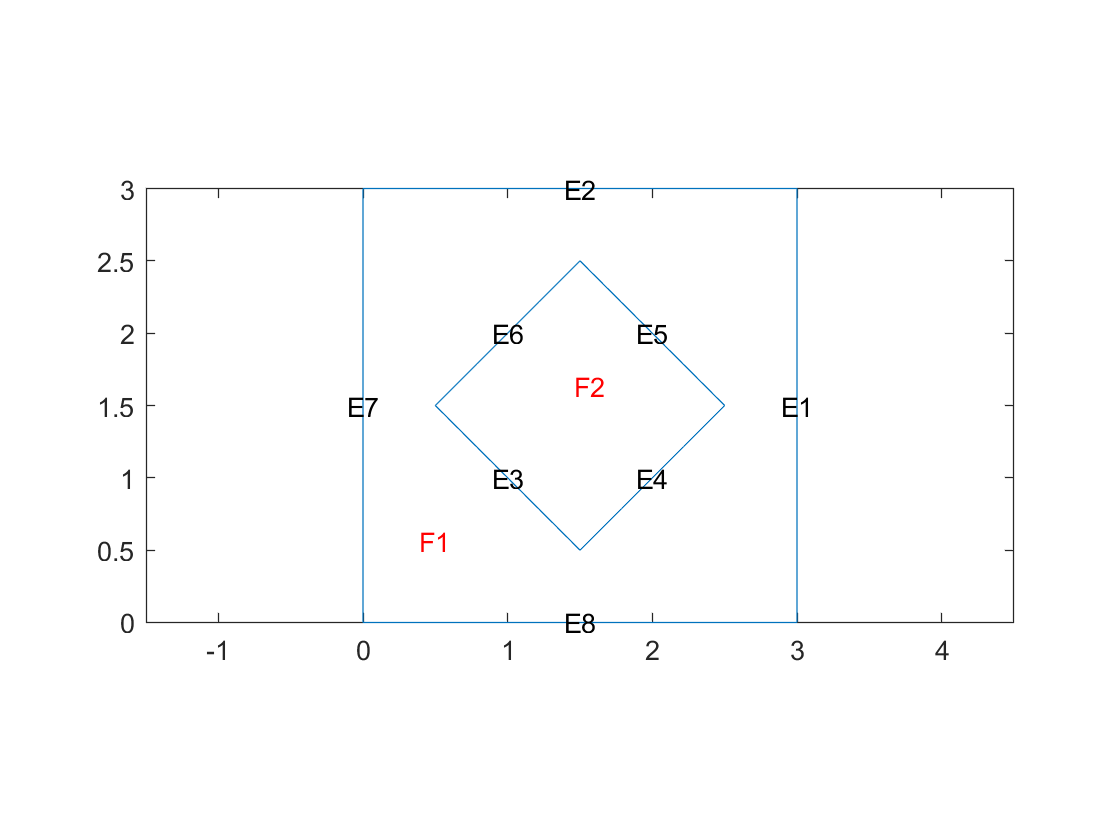

SQ1 = [3; 4; 0; 3; 3; 0; 0; 0; 3; 3];
D1 = [2; 4; 0.5; 1.5; 2.5; 1.5; 1.5; 0.5; 1.5; 2.5];
gd = [SQ1 D1];
sf = 'SQ1+D1';
ns = char('SQ1','D1');
ns = ns';
dl = decsg(gd,sf,ns);
geometryFromEdges(thermalmodel,dl);
pdegplot(thermalmodel,'EdgeLabels','on','FaceLabels','on')
xlim([-1.5 4.5])
ylim([-0.5 3.5])
axis equal

For the square region, assign these thermal properties:

- Thermal conductivity is 10 W/(m⋅∘C)

- Mass density is 2 kg/m3

- Specific heat is 0.1 J/(kg⋅∘C)

thermalProperties(thermalmodel,'ThermalConductivity',10, ...
                               'MassDensity',2, ...
                               'SpecificHeat',0.1, ...
                               'Face',1);

For the diamond region, assign these thermal properties:

- Thermal conductivity is 2 W/(m⋅∘C)

- Mass density is 1 kg/m3

- Specific heat is 0.1J/ (kg⋅∘C)

thermalProperties(thermalmodel,'ThermalConductivity',2, ...
                               'MassDensity',1, ...
                               'SpecificHeat',0.1, ...
                               'Face',2);
                      

Assume that the diamond-shaped region is a heat source with a density of 4 W/m^2.

internalHeatSource(thermalmodel,4,'Face',2);

Apply a constant temperature of 0∘*C* to the sides of the square plate.

thermalBC(thermalmodel,'Temperature',0,'Edge',[1 2 7 8]);

Set the initial temperature to 0 **°**C.

thermalIC(thermalmodel,0) 

ans =   GeometricThermalICs - 属性:

            RegionType: 'face'
              RegionID: [1 2]
    InitialTemperature: 0


Generate the mesh.

generateMesh(thermalmodel);

The dynamics for this problem are very fast. The temperature reaches a steady state in about 0.1 seconds. To capture the interesting part of the dynamics, set the solution time to `logspace(-2,-1,10)`. This command returns 10 logarithmically spaced solution times between 0.01 and 0.1.

tlist = logspace(-2,-1,10);

solve the equ.

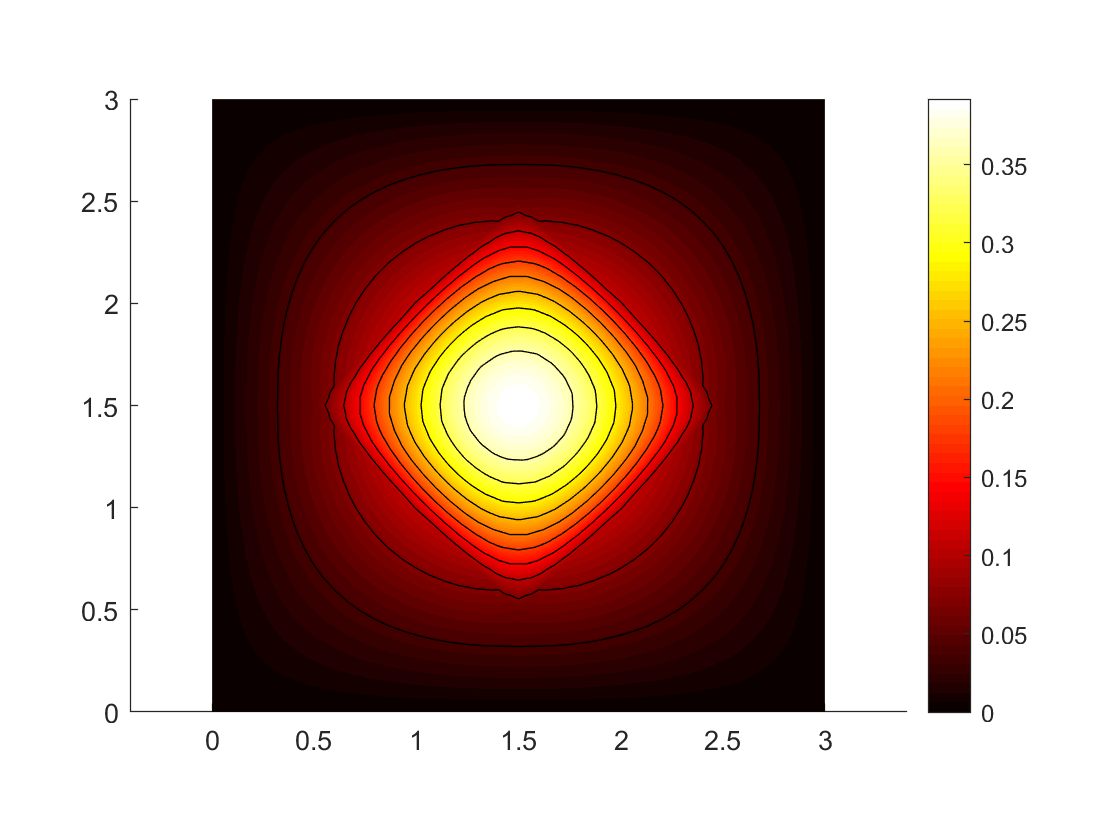

thermalresults = solve(thermalmodel,tlist);
T = thermalresults.Temperature;
pdeplot(thermalmodel,'XYData',T(:,10),'Contour','on','ColorMap','hot')

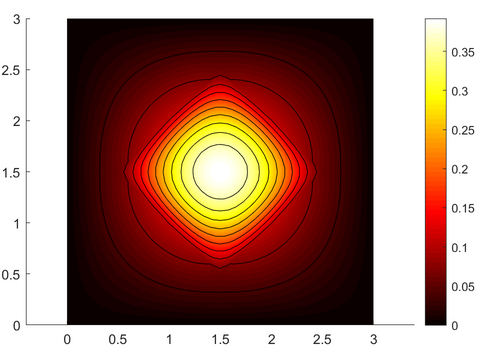

改变tlist可以控制模拟的时间。